time4 = DYOErun11652320.AnalogChannels; 
signal4 = DYOErun11652320.VarName5; 
k = [time4,signal4]; 

% determine sampling frequency
Fs = 1 / mean(diff(time4));  % Sampling frequency in Hz



% analyze frequency components
Y = fft(signal4);
L = length(signal4);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

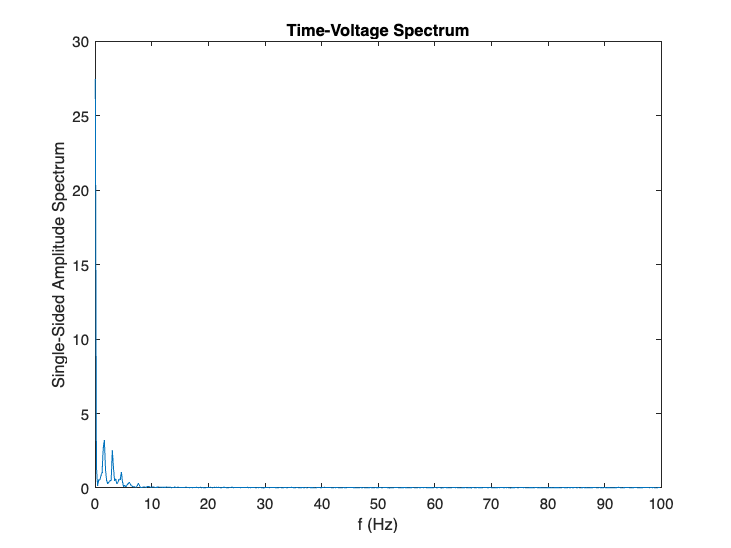

P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f, P1);
title('Time-Voltage Spectrum');
xlabel('f (Hz)');
ylabel('Single-Sided Amplitude Spectrum');

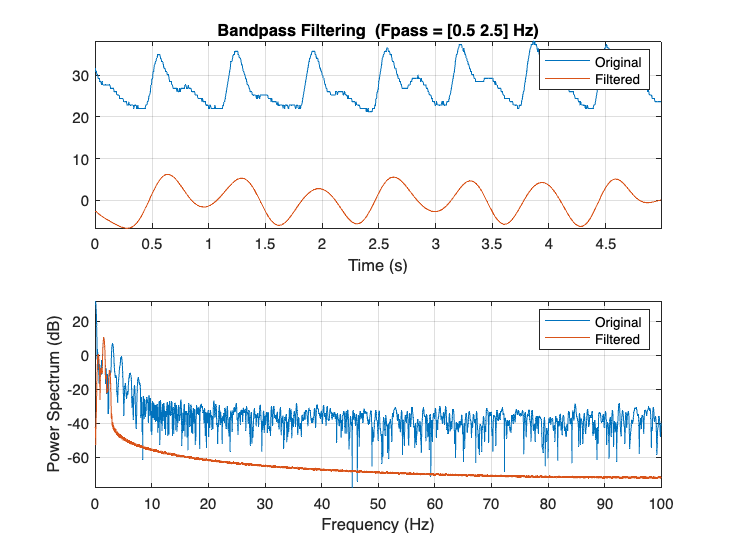

bandpass(signal4,[0.5 2.5],Fs)